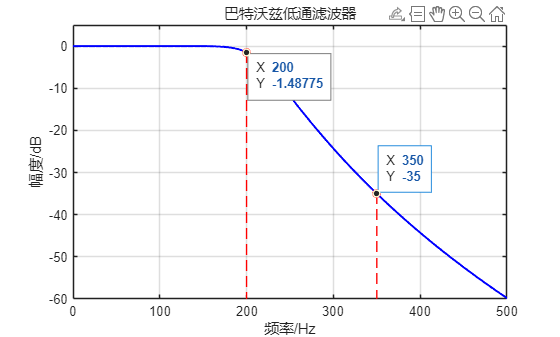

%% 利用buttord、butter函数编程实现巴特沃兹模拟低通滤波器
% 要求f_p=200Hz，δ_p≤3dB，f_s=350Hz，δ_s≥35dB，T=1ms。画出滤波器的幅频特性曲线

fp = 200;      % 通带截止频率(Hz)
fs = 350;      % 阻带起始频率(Hz)
dp = 3;        % 通带衰减最大值(dB)
ds = 35;       % 阻带衰减最小值(dB)
T = 1/1000;    % 采样间隔1ms
fT = 1/T;      % 采样频率1000Hz

% 转换为角频率(rad/s)
Wp = 2*pi*fp;  % 通带截止角频率
Ws = 2*pi*fs;  % 阻带起始角频率

% 计算滤波器阶数和截止频率
[n, Wn] = buttord(Wp, Ws, dp, ds, 's');

% 设计巴特沃兹低通滤波器
[num, den] = butter(n, Wn, 'low', 's');

% 生成频率点
fk = 0:1:1000;  % 频率从0到1000Hz，步长1Hz
wk = 2*pi*fk;   % 转换为角频率

% 计算频率响应
Hk = freqs(num, den, wk);
Hk_dB = 20*log10(abs(Hk));

% 绘制幅频特性曲线
figure;
plot(fk, Hk_dB, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('频率/Hz');
ylabel('幅度/dB');
title('巴特沃兹低通滤波器');
hold on;

fp_index = find(fk == fp);
fs_index = find(fk == fs);
fp_magnitude = Hk_dB(fp_index);
fs_magnitude = Hk_dB(fs_index);
plot([fp, fp], [fp_magnitude, -110], 'r--', 'LineWidth', 1);
plot([fs, fs], [fs_magnitude, -110], 'r--', 'LineWidth', 1);
% plot([0, 1000], [fp_magnitude, fp_magnitude], 'g--', 'LineWidth', 0.5);
% plot([0, 1000], [fs_magnitude, fs_magnitude], 'g--', 'LineWidth', 0.5);
plot(fp, fp_magnitude, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'red');
plot(fs, fs_magnitude, 'ro', 'MarkerSize', 6, 'MarkerFaceColor', 'red');
axis([0, 500, -60, 5]);